## Problem 1

First start by throwing a signal-free background. For Problem 1 choose a Normal distribution with some modest *σ*, say in the range 2-5. Create a million background events.

background_standard_dev = 3;
background_mean = 0;
number_of_events = 1000000;

background_events = normrnd(background_mean, background_standard_dev, [1,number_of_events]);

Now we need to make some signal. Let us choose to make signals of  random strength on the interval of 0-20. Now it is critically important  that you throw these using a *uniform* distribution. A uniform  distribution means that the signal is equally likely to be small/faint  (near zero) as large/bright (near 20). Mathematically this is the *P*(*s**i**g**n**a**l*) in the equation. If you use another way of simulating signals that does not have a uniform distribution, you are injecting an *implicit* prior (very, very bad).

signal_min = 0;
signal_max = 20;

true_signal = signal_min + (signal_max - signal_min)*rand(1, number_of_events);

Now add your signal to your background to create fake data readings.  Since you know what the true signal was for each data reading, and you  used a flat prior, you now have *P*(*d**a**t**a*|*s**i**g**n**a**l*)*P*(*s**i**g**n**a**l*).

measured_values = background_events + true_signal;

Now make one of the 2D histograms as shown in class. Here we want to  histogram the signal vs. the simulated data readings. There are a couple of ways to do this, but it will be easier later if you define your bin  edges explicitly, make a histogram, then plot it. 

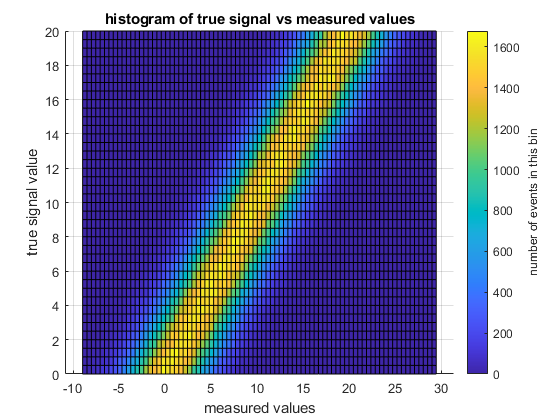

std_buffer = 3;
number_of_steps_x = 80;
xmin = signal_min+background_mean-std_buffer*background_standard_dev;
xstep = (signal_max - signal_min + (2*std_buffer)*background_standard_dev)/number_of_steps_x;
xmax = (signal_max + background_mean + std_buffer*background_standard_dev);
xrange = xmin:xstep:xmax;

number_of_steps_y = 40;
ymin = signal_min;
ystep = (signal_max - signal_min)/number_of_steps_y;
ymax = signal_max;
yrange = ymin:ystep:ymax;
edges = { xrange yrange};

figure;
hist3([measured_values', true_signal'], 'Edges', edges,'CDataMode','auto', 'FaceColor', 'interp');
c = colorbar;
c.Label.String = 'number of events in this bin';
title('histogram of true signal vs measured values');
xlabel(['measured values']);
ylim([0,20])
ylabel(['true signal value']);
view(2)

**Problem 1b**

Select a true injected signal and plot *P*(*d*|*s*). (Use a stair style plot). Label your plot and *clearly* explain what you are plotting and how to interpret it. [Hint: this was also shown in class.]

For plotting measured signal at a fixed true signal, I will be including all the point from the above plot that fall in the same histogram as the true signal value.

true_injected_signal = 9.3;

edge_more_than_signal = yrange > true_injected_signal;
indices = find(edge_more_than_signal);
upper_edge = yrange(indices(1))

upper_edge =    9.500000000000000


lower_edge = yrange(indices(1)-1)

lower_edge =      9


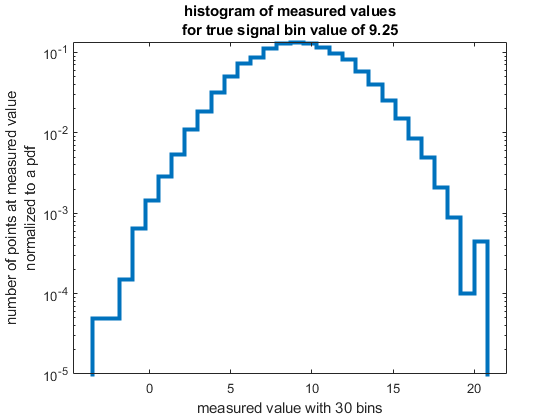

bin_center = mean([lower_edge upper_edge]);

true_signals_above_lower_edge = true_signal > lower_edge;
true_signals_below_upper_edge = true_signal < upper_edge;
true_signal_in_range_indices = find(true_signals_above_lower_edge .* true_signals_below_upper_edge);

corresponding_measured = measured_values(true_signal_in_range_indices);

nbins = 30;
figure
histogram(corresponding_measured, nbins,'DisplayStyle',"stairs",'LineWidth',3, "Normalization","pdf")
title({'histogram of measured values' ['for true signal bin value of ' num2str(bin_center)]})
ylabel({'number of points at measured value' 'normalized to a pdf'})
xlabel(['measured value with ' num2str(nbins) ' bins'])
set(gca, 'Yscale', 'log')

This plot describes the probability of measuring a value given a true signal value. Specifically it is a normalized histogram of the measured values that correspond to signal values that are in the same histogram bin in 1a as the selected signal. In this case, for a selected signal of 9.3, that corresponds to the bin of true signal values between 9 and 9.5. This is then a histogram of the measured values corresponding with all true signal values between 9 and 9.5. It describes the distribution of measured values given the true signal falls (with uniform probability) between the bounds of 9 and 9.5. 

**Problem 1c**

Select an observed data value and plot *P*(*s*|*d*). (Use a stair style plot). Label your plot and *clearly* explain what you are plotting and how to interpret it.

measured_signal = 14;

edge_more_than_signal = xrange > measured_signal;
indices = find(edge_more_than_signal);
upper_edge = xrange(indices(1))

upper_edge =   14.275000000000000


lower_edge = xrange(indices(1)-1)

lower_edge =   13.800000000000001


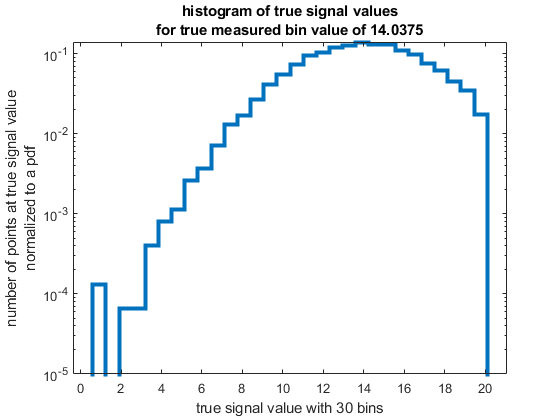

bin_center = mean([lower_edge upper_edge]);

measured_signals_above_lower_edge = measured_values > lower_edge;
measured_signals_below_upper_edge = measured_values < upper_edge;
measured_signal_in_range_indices = find(measured_signals_above_lower_edge .* measured_signals_below_upper_edge);

corresponding_true = true_signal(measured_signal_in_range_indices);

nbins = 30;
figure
histogram(corresponding_true, nbins,'DisplayStyle',"stairs",'LineWidth',3, "Normalization","pdf")
title({'histogram of true signal values' ['for true measured bin value of ' num2str(bin_center)]})
ylabel({'number of points at true signal value' 'normalized to a pdf'})
xlabel(['true signal value with ' num2str(nbins) ' bins'])
set(gca, 'Yscale', 'log')

This plot describes the probability of the true signal value behind the measured signal value. Specifically it is a normalized histogram of the true signal values that correspond to measured values that are in the same histogram bin in 1a as the selected signal. In this case, for a selected measured signal of  14, that corresponds to the bin of true signal values between 13.8 and 14.275. This is then a histogram of the true signal values corresponding to all measured signal values between 13.8 and 14.275. It describes the distribution of true signal values given the measured signal falls between the bounds of 13.8 and 14.275. Interestingly, it appears truncated on the right side. This is because the true signal values are restricted to be between 0 and 20, so there is no true signal value above 20. 

## Problem 2

Now repeat the above, but with a background with non-zero mean. The easiest way would be to still have Guassian distribution but with a non-zero  mean. [Hint: move it by at least a couple of *σ*]. Reproduce the graphs above. Lastly overplot the *P*(*d*|*s*) and *P*(*s*|*d*) plots. Why are they not centered on the same value? Explain carefully.

background_standard_dev = 3;
background_mean = 10;
number_of_events = 1000000;

background_events = normrnd(background_mean, background_standard_dev, [1,number_of_events]);

Now we need to make some signal. Let us choose to make signals of  random strength on the interval of 0-20. Now it is critically important  that you throw these using a *uniform* distribution. A uniform  distribution means that the signal is equally likely to be small/faint  (near zero) as large/bright (near 20). Mathematically this is the *P*(*s**i**g**n**a**l*) in the equation. If you use another way of simulating signals that does not have a uniform distribution, you are injecting an *implicit* prior (very, very bad).

signal_min = 0;
signal_max = 20;

true_signal = signal_min + (signal_max - signal_min)*rand(1, number_of_events);

Now add your signal to your background to create fake data readings.  Since you know what the true signal was for each data reading, and you  used a flat prior, you now have *P*(*d**a**t**a*|*s**i**g**n**a**l*)*P*(*s**i**g**n**a**l*).

measured_values = background_events + true_signal;

Now make one of the 2D histograms as shown in class. Here we want to  histogram the signal vs. the simulated data readings. There are a couple of ways to do this, but it will be easier later if you define your bin  edges explicitly, make a histogram, then plot it. 

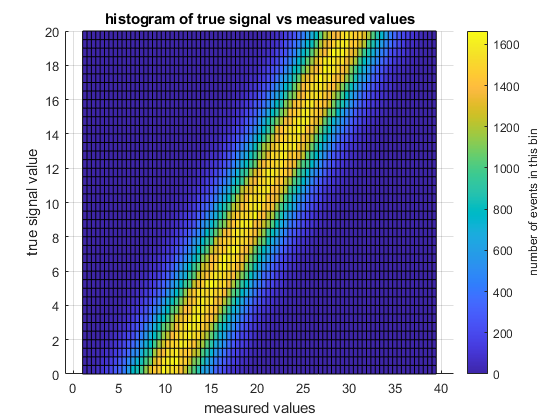

std_buffer = 3;
number_of_steps_x = 80;
xmin = signal_min+background_mean-std_buffer*background_standard_dev;
xstep = (signal_max - signal_min + (2*std_buffer)*background_standard_dev)/number_of_steps_x;
xmax = (signal_max + background_mean + std_buffer*background_standard_dev);
xrange = xmin:xstep:xmax;

number_of_steps_y = 40;
ymin = signal_min;
ystep = (signal_max - signal_min)/number_of_steps_y;
ymax = signal_max;
yrange = ymin:ystep:ymax;
edges = { xrange yrange};

figure;
hist3([measured_values', true_signal'], 'Edges', edges,'CDataMode','auto', 'FaceColor', 'interp');
c = colorbar;
c.Label.String = 'number of events in this bin';
title('histogram of true signal vs measured values');
xlabel(['measured values']);
ylim([0,20])
ylabel(['true signal value']);
view(2)

**Problem 2b**

Select a true injected signal and plot *P*(*d*|*s*). (Use a stair style plot). Label your plot and *clearly* explain what you are plotting and how to interpret it. [Hint: this was also shown in class.]

For plotting measured signal at a fixed true signal, I will be including all the point from the above plot that fall in the same histogram as the true signal value.

true_injected_signal = 9.3;

edge_more_than_signal = yrange > true_injected_signal;
indices = find(edge_more_than_signal);
upper_edge = yrange(indices(1))

upper_edge =    9.500000000000000


lower_edge = yrange(indices(1)-1)

lower_edge =      9


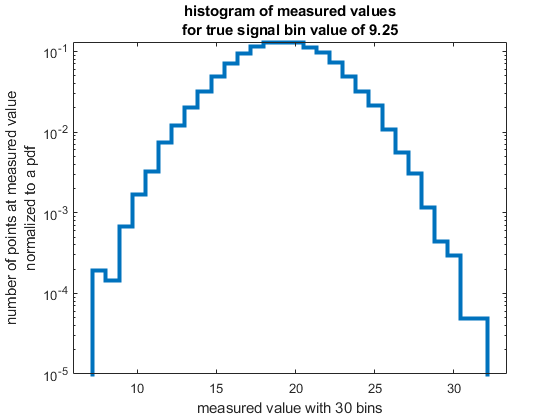

bin_center = mean([lower_edge upper_edge]);

true_signals_above_lower_edge = true_signal > lower_edge;
true_signals_below_upper_edge = true_signal < upper_edge;
true_signal_in_range_indices = find(true_signals_above_lower_edge .* true_signals_below_upper_edge);

corresponding_measured = measured_values(true_signal_in_range_indices);

nbins = 30;
figure
histogram(corresponding_measured, nbins,'DisplayStyle',"stairs",'LineWidth',3, "Normalization","pdf")
title({'histogram of measured values' ['for true signal bin value of ' num2str(bin_center)]})
ylabel({'number of points at measured value' 'normalized to a pdf'})
xlabel(['measured value with ' num2str(nbins) ' bins'])
set(gca, 'Yscale', 'log')

This plot describes the probability of measuring a value given a true signal value. Specifically it is a normalized histogram of the measured values that correspond to signal values that are in the same histogram bin in 1a as the selected signal. In this case, for a selected signal of 9.3, that corresponds to the bin of true signal values between 9 and 9.5. This is then a histogram of the measured values corresponding with all true signal values between 9 and 9.5. It describes the distribution of measured values given the true signal falls (with uniform probability) between the bounds of 9 and 9.5. 

**Problem 2c**

Select an observed data value and plot *P*(*s*|*d*). (Use a stair style plot). Label your plot and *clearly* explain what you are plotting and how to interpret it.

measured_signal = 19.2;

edge_more_than_signal = xrange > measured_signal;
indices = find(edge_more_than_signal);
upper_edge = xrange(indices(1))

upper_edge =   19.524999999999999


lower_edge = xrange(indices(1)-1)

lower_edge =   19.050000000000001


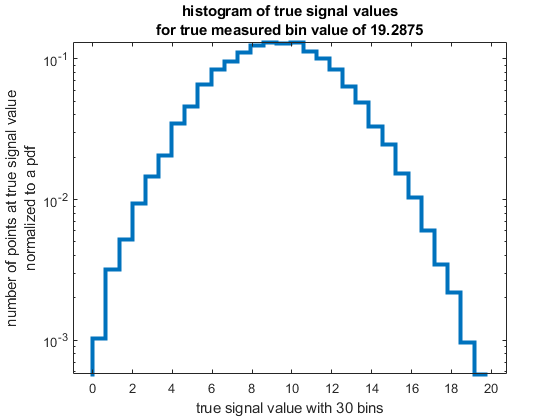

bin_center = mean([lower_edge upper_edge]);

measured_signals_above_lower_edge = measured_values > lower_edge;
measured_signals_below_upper_edge = measured_values < upper_edge;
measured_signal_in_range_indices = find(measured_signals_above_lower_edge .* measured_signals_below_upper_edge);

corresponding_true = true_signal(measured_signal_in_range_indices);

nbins = 30;
figure
histogram(corresponding_true, nbins,'DisplayStyle',"stairs",'LineWidth',3, "Normalization","pdf")
title({'histogram of true signal values' ['for true measured bin value of ' num2str(bin_center)]})
ylabel({'number of points at true signal value' 'normalized to a pdf'})
xlabel(['true signal value with ' num2str(nbins) ' bins'])
set(gca, 'Yscale', 'log')

This plot describes the probability of the true signal value behind the measured signal value. Specifically it is a normalized histogram of the true signal values that correspond to measured values that are in the same histogram bin in 1a as the selected signal. In this case, for a selected measured signal of 19.2, that corresponds to the bin of true signal values between 19.05 and 19.525. This is then a histogram of the true signal values corresponding to all measured signal values between 19.05 and 19.525. It describes the distribution of true signal values given the measured signal falls between the bounds of 19.05 and 19.525. 

Lastly overplot the *P*(*d*|*s*) and *P*(*s*|*d*) plots. Why are they not centered on the same value? Explain carefully.

These are not centered on the same value because I did not choose the measured signal and true signals for the two to be the same. But even if I did, the measured signal is biased. Because the background distribution now has a non-zero mean, even though it is symmetric the measured signals we expect to see are (almost always) larger than the true signal. Thus, the distribution of true signals at a given measured signal is shifted to be less than the measured signal, while the distribution of measured signals given a true signal is shifted to be more than the true signal.

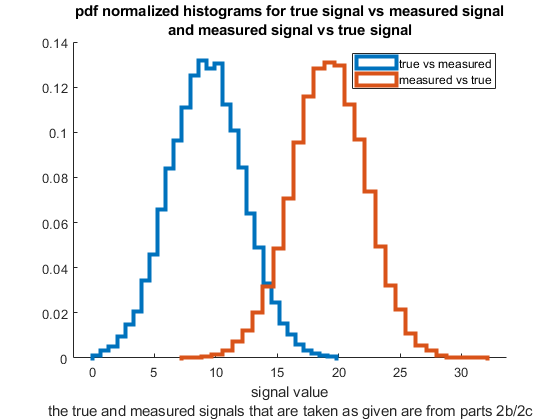

figure
hold on
histogram(corresponding_true, nbins,'DisplayStyle',"stairs",'LineWidth',3, "Normalization","pdf")
histogram(corresponding_measured, nbins,'DisplayStyle',"stairs",'LineWidth',3, "Normalization","pdf")
title({'pdf normalized histograms for true signal given a measured signal' 'and measured signal given a true signal'})
legend({'true given measured' 'measured given true'})
xlabel({'signal value' 'the true and measured signals that are taken as given are from parts 2b/2c'})